# Broadband tutorial

## Load sample data

datasets = {'sample data'  'sample data envelope'  'gamma irf'  'dcts irf' 'square wave'};
whichData = datasets{1};

% Load the sample data
load ECoG_sample_data_01

switch whichData
    case 'sample data'
        % Do nothing. Use the sample data set we loaded.
        
    case 'sample data envelope'
        % Replace the sample data with a simulation of the sample data.
        % The simulated data was derived by extracting the time-varying
        % broadband envelope of the same data, and treating this as a latent rate:
        % this rate was multiplied point-wise by Gaussian white noise.
        load ECoG_simulated_data_01;
        data = sim.spikes;
        
        
    case 'gamma irf'
        % Gamma function
        tau1 = 0.01; tau2 = 0.05; delay_t = 0.130;
        gamma1 = max((t_e-delay_t),0).*exp(-(t_e-delay_t)/tau1);
        gamma2 = max((t_e-delay_t),0).*exp(-(t_e-delay_t)/tau2);
        irf = gamma1/sum(gamma1); % - gamma2/sum(gamma2);
        irf = irf-min(irf);
        irf = irf/max(irf);
        
    case 'square wave'
        % Gamma function
        irf = (t_e > .5) + 1;
        
        
    case 'dcts irf'
        % dCTS prediction
        tmp = load('dCTS_pred');
        irf = tmp.irf;
end


## Epoch the data


% Time and frequency definitions
t = (1:size(data,1))/srate;
f = (0:length(t)-1)/max(t);

%% Epoch the data
blank   = find(strcmp(stimnames, 'blank'));
targets = find(strcmp(stimnames, 'white noise') | ...
    strcmp(stimnames, 'pink noise') | ...
    strcmp(stimnames, 'brown noise'));
targets = 1:7;
stim_onsets = round(onsets(ismember(stims, targets)));

all_onsets = round(onsets(stims ~= blank));
nt = median(diff(all_onsets));

epochs = zeros(nt, length(stim_onsets));
for ii = 1:length(stim_onsets)
    epochs(:,ii) = stim_onsets(ii)+(0:nt-1);
end

% Set first onset to t=0
t    = t-t(stim_onsets(1));

% Define time for a single epoch
t_e  = t(stim_onsets(1)+(0:nt-1))';

% Frequencies for a single epoch
f_e = (0:length(t_e)-1)/max(t_e);


## Apply IRF

switch whichData
    case {'sample data' 'sample data envelope'}
        signal.raw = data;
    case {'gamma irf' 'dcts irf' 'square wave'}
        % Apply the irf as a scale factor on Gaussian white noise
        signal.sim = randn(size(data));
        signal.tmp = bsxfun(@times, signal.sim(epochs), irf+1);
        signal.sim(epochs) = signal.tmp;
        signal.raw = signal.sim;
end

## Plot time series and spectrum

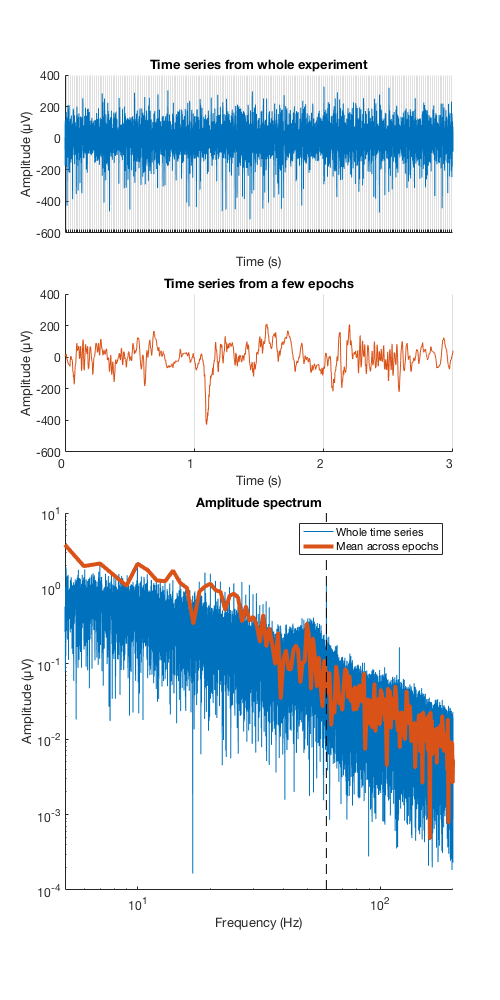


figure(1); clf; pos = get(gcf, 'Position'); pos([3 4]) = [500 1000];
set(gcf, 'Color', 'w', 'Position', pos);


%  Plot the whole time series
subplot(4,1,1)
set(gca, 'FontSize', 12, 'XTick', t(stim_onsets), 'XGrid', 'on', ...
    'XTickLabel', ' '); hold on
plot(t, signal.raw);
xlabel('Time (s)'); ylabel('Amplitude (µV)')
xlim(t([stim_onsets(1) stim_onsets(end)+nt]));
title('Time series from whole experiment');

%  Plot the time series for a few epochs
subplot(4,1,2)
set(gca, 'FontSize', 12, 'XTick', t(stim_onsets), 'XGrid', 'on', ...
    'XTickLabel', round(t(stim_onsets))); hold on
plot(t, signal.raw, t, signal.raw);
xlabel('Time (s)'); ylabel('Amplitude (µV)')
xlim(t([stim_onsets(1) stim_onsets(4)]));
title('Time series from a few epochs');

% Plot spectrum
subplot(4,1, 3:4)

set(gcf, 'Color', 'w'); set(gca, 'FontSize', 12), hold on
plot(f, abs(fft(signal.raw))/length(t));
plot(f_e, abs(fft(mean(signal.raw(epochs),2)))/length(t_e), ...
    'LineWidth', 4);
set(gca, 'XScale', 'log', 'YScale', 'log')
xlim([5 200])
plot([60 60], get(gca, 'YLim'), 'k--')
xlabel('Frequency (Hz)')
ylabel('Amplitude (µV)')
legend('Whole time series', 'Mean across epochs');
title('Amplitude spectrum');

## Define bands for subsequent band pass filtering

% Entire range for broadband
band_rg  = [60 200];
% Bin width for extracting narrower bins within the broadband range
band_w   = 20;
% Show bins
lb       = band_rg(1):band_w:band_rg(2)-band_w;
ub       = lb+band_w;
bands   = [lb; ub]';
numbands = size(bands,1);
disp(bands)

    60    80
    80   100
   100   120
   120   140
   140   160
   160   180
   180   200



## Envelope of single, large band

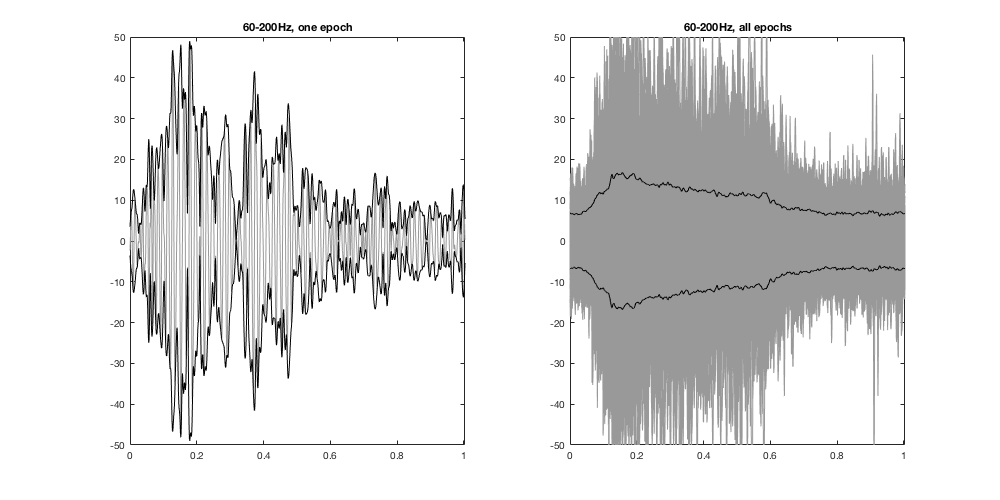

% First, we band pass filter the whole broadband range at once (and compute the envelope)
signal.bp_single = butterpass_eeglabdata(signal.raw,band_rg,srate);
signal.bp_envelope = abs(hilbert(signal.bp_single));

%% Plot the band pass filtered time series and envelope for one large band
fH = figure(3); clf; set(fH, 'Color', 'w')
% make figure wide
pos = get(fH, 'position'); pos([3 4]) = [1000 500];
set(fH, 'Position', pos);

% time for one epoch
idx = stim_onsets(1)+(0:nt-1);
xl = [t(idx(1)) t(idx(end))];
subplot(1,2,1)
plot(t_e, signal.bp_single(idx), 'LineWidth', 1, 'Color', .6 * [1 1 1]); hold on
plot(t_e, signal.bp_envelope(idx)*[1 -1], 'LineWidth', 1, 'Color', 'k');
yl = get(gca, 'YLim');
xlim(xl)
title(sprintf('%d-%dHz, one epoch', bands(1), bands(end)));

subplot(1,2,2)
plot(t_e, signal.bp_single(epochs), 'LineWidth', 1, 'Color', .6 * [1 1 1]); hold on
plot(t_e, mean(signal.bp_envelope(epochs),2)*[1 -1], 'LineWidth', 1, 'Color', 'k');

axis([xl yl])
title(sprintf('%d-%dHz, all epochs', bands(1), bands(end)));

## Separate envelopes for each sub-band

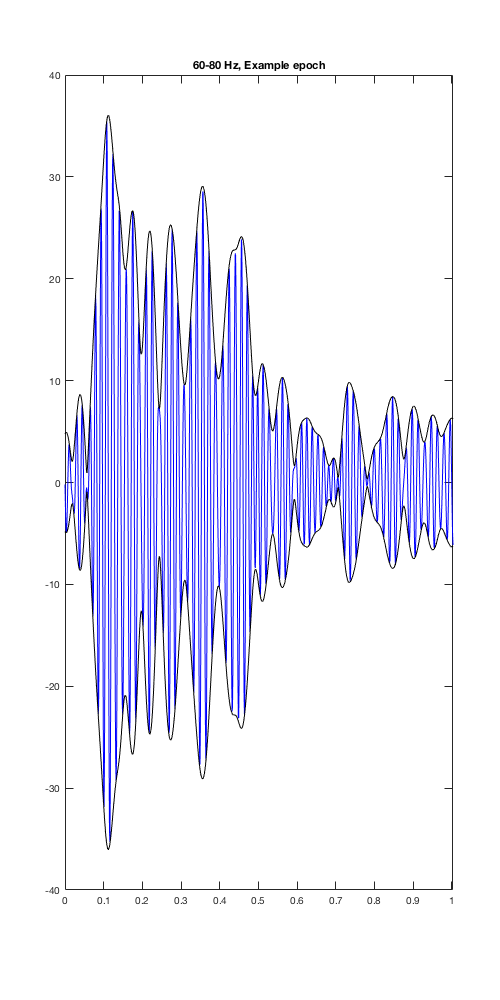

% band pass filter each sub-band
signal.bp_multi  = zeros(length(signal.raw),size(bands,1));
for ii = 1:size(bands,1)
    signal.bp_multi(:,ii) = butterpass_eeglabdata(signal.raw,bands(ii,:),srate);
end

% envelope of sub-bands
signal.bp_envelopes = abs(hilbert(signal.bp_multi));

% Plot them
fH = figure(4); clf; set(fH, 'Color', 'w')

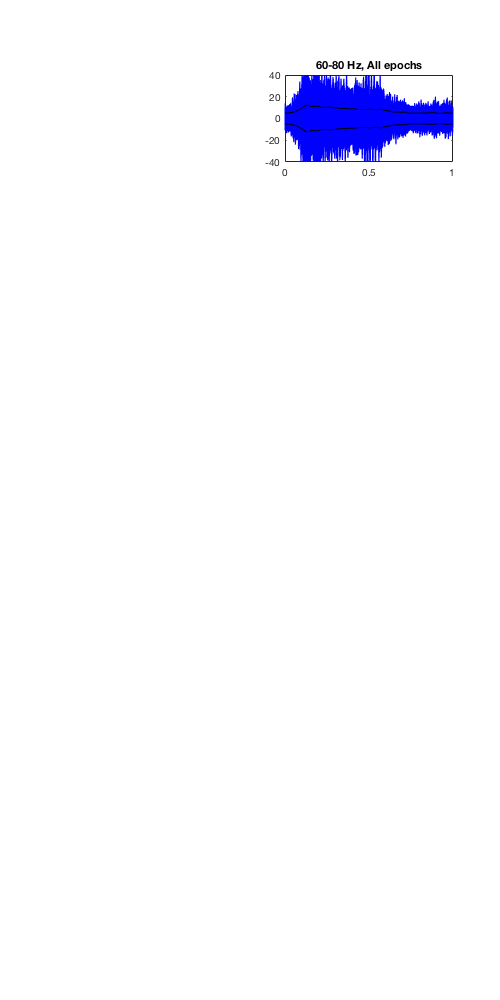

pos = get(fH, 'position'); pos([3 4]) = [500 1000]; set(fH, 'Position', pos);

colors = jet(numbands);
for ii = 1%:numbands
    % Plot one epoch
    %subplot(numbands,2,ii*2-1)
    this_ts = signal.bp_multi(:,ii);
    this_en = signal.bp_envelopes(:,ii);
    plot(t_e, this_ts(idx), 'LineWidth', 1, 'Color', colors(ii,:)); hold on
    plot(t_e, this_en(idx)*[1 -1], 'LineWidth', 1, 'Color', 'k');
    xlim(xl); yl = get(gca, 'YLim');
    title(sprintf('%d-%d Hz, Example epoch', bands(ii,1), bands(ii,2)));
    
    % Plot all epochs
    subplot(numbands,2,ii*2)
    plot(t_e, this_ts(epochs), 'LineWidth', 1, 'Color', colors(ii,:)); hold on
    plot(t_e, mean(this_en(epochs),2)*[1 -1], 'LineWidth', 1, 'Color', 'k');
    
    axis([xl yl])
    title(sprintf('%d-%d Hz, All epochs', bands(ii,1), bands(ii,2)));
end

## Compare envelopes of different sub-bands

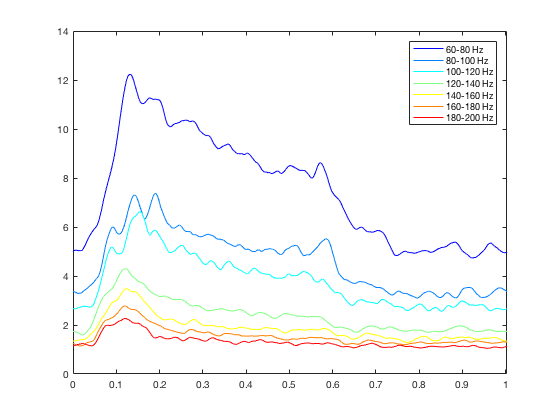

fH = figure; clf; set(fH, 'Color', 'w')

colors = jet(numbands);
for ii = 1:numbands
    % Plot one epoch
    this_en = signal.bp_envelopes(:,ii);
    plot(t_e, mean(this_en(epochs),2), 'LineWidth', 1,  'Color', colors(ii,:));  hold on
    xlim(xl); yl = get(gca, 'YLim');
    legend_txt{ii} = sprintf('%d-%d Hz', bands(ii,1), bands(ii,2));
end
legend(legend_txt)

## Compare different methods of deriving broadband envelopes

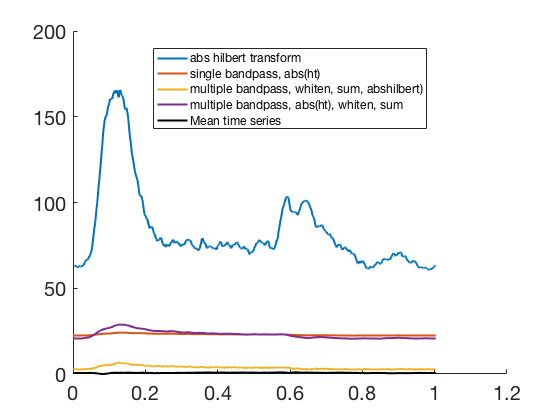

whiten = @(x) bsxfun(@plus, zscore(x), mean(x));
scale_0_1 = @(x) (x - min(x(:))) / (max(x(:)) - min(x(:)));

% -- Method 1: abs(hilbert) (no filtering) -----------------------------
signal.bb{1} = abs(hilbert(signal.raw));
str = []; str{1} = 'abs hilbert transform';

% --  Method 2: single bandpass, abs(hilbert) --------------------------
%signal.bb{2} = (abs(hilbert(signal.bp_single)));
signal.bb{2} = whiten(sum(abs(hilbert(signal.bp_multi)),2));

str{2} = 'single bandpass, abs(ht)';

% -- Method 3: multiple bandpass, whiten, sum, abs(hilbert) ------------
signal.bb{3} = abs(hilbert(sum(zscore(signal.bp_multi),2)));
str{3} = 'multiple bandpass, whiten, sum, abshilbert)';

% -- Method 4: multiple bandpass, abs(hilbert), whiten, sum ------------
signal.bb{4} = sum(whiten(abs(hilbert(signal.bp_multi))),2);
str{4} = 'multiple bandpass, abs(ht), whiten, sum';

fH = figure; set(fH, 'Color', 'w')
set(gca, 'FontSize', 20)
hold on;
numbb = length(signal.bb);

for ii = 1:numbb
    y = mean(signal.bb{ii}(epochs),2);
    plot(t_e, y, 'LineWidth', 2);
    %plot(t_e, scale_0_1(y), 'LineWidth', 2);
end

plot(t_e, scale_0_1(mean(signal.raw(epochs),2)), 'k', 'LineWidth', 2);
legend([str 'Mean time series'], 'FontSize', 12, 'Location', 'Best')

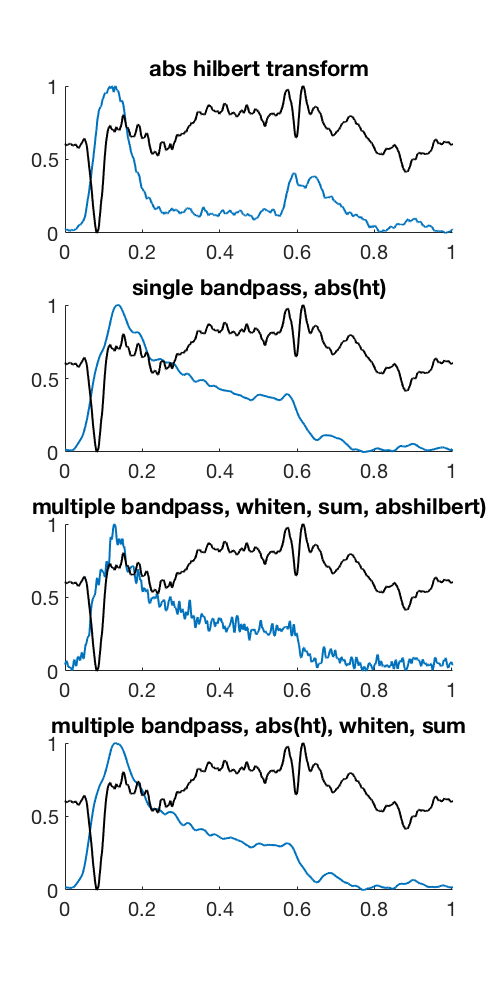

fH = figure; set(fH, 'Color', 'w')
pos = get(fH, 'position'); pos([3 4]) = [500 1000]; set(fH, 'Position', pos);
numbb = length(signal.bb);

for ii = 1:numbb
    subplot(numbb,1,ii)
    set(gca, 'FontSize', 20)
    hold on
    y = mean(signal.bb{ii}(epochs),2);
    plot(t_e, scale_0_1(y), 'LineWidth', 2);
    plot(t_e, scale_0_1(mean(signal.raw(epochs),2)), 'k', 'LineWidth', 2);
    title(str{ii})
    axis tight
end


return

## Save simulated data

sim.rate   = signal.bb{4};
sim.spikes = randn(size(sim.rate)) .* sim.rate;
sim.lfp    = zeros(size(sim.spikes));
tau = 0.01;
for ii = 1:length(sim.lfp)
    % rate of change in current
    dI = (sim.spikes(ii) - sim.lfp(ii)) / tau / srate;
    % current at next time point
    sim.lfp(ii+1) = sim.lfp(ii) + dI;
end
figure,
subplot(3,1,1)
plot(sim.rate(epochs))

subplot(3,1,2)
plot(sim.spikes(epochs))

subplot(3,1,3)
plot(sim.lfp(epochs))
data = sim.lfp;
save ECoG_simulated_data_01 srate onsets stims stimnames sim

